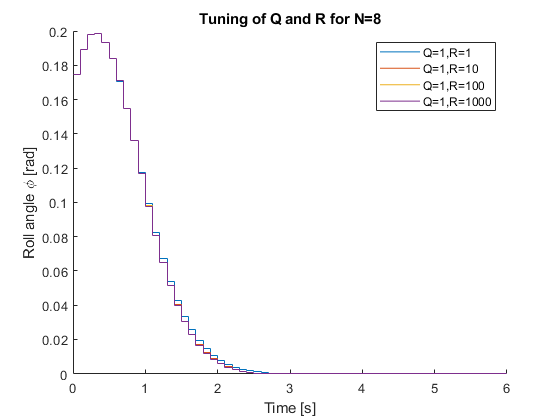

clear all
close all

xlim = 60;
t = linspace(0,6,60+1);

load('MPC_reg_states_N_8\States_N_8_v_2_Q_0_001_R_1.mat')
x_Q_0_001_R_1 = x;

load('MPC_reg_states_N_8\States_N_8_v_2_Q_0_01_R_1.mat')
x_Q_0_01_R_1 = x;

load('MPC_reg_states_N_8\States_N_8_v_2_Q_0_1_R_1.mat')
x_Q_0_1_R_1 = x;

load('MPC_reg_states_N_8\States_N_8_v_2_Q_1_R_1.mat')
x_Q_1_R_1 = x;

load('MPC_reg_states_N_8\States_N_8_v_2_Q_10_R_1.mat')
x_Q_10_R_1 = x;

load('MPC_reg_states_N_8\States_N_8_v_2_Q_100_R_1.mat')
x_Q_100_R_1 = x;

load('MPC_reg_states_N_8\States_N_8_v_2_Q_1000_R_1.mat')
x_Q_1000_R_1 = x;

% load('MPC_reg_states_N_8\States_N_8_v_2_Q_10000_R_1.mat')
% x_Q_10000_R_1 = x;
% 
% load('MPC_reg_states_N_8\States_N_8_v_2_Q_100000_R_1.mat')
% x_Q_100000_R_1 = x;

figure(1)
hold on
stairs(t,x_Q_1_R_1(1,:))
stairs(t,x_Q_0_1_R_1(1,:))
stairs(t,x_Q_0_01_R_1(1,:))
stairs(t,x_Q_0_001_R_1(1,:))
% stairs(t,x_Q_10_R_1(1,:))
% stairs(t,x_Q_100_R_1(1,:))
% stairs(t,x_Q_1000_R_1(1,:))
% stairs(t,x_Q_10000_R_1(1,:))
% stairs(t,x_Q_100000_R_1(1,:))
legend('Q=1,R=1','Q=1,R=10','Q=1,R=100','Q=1,R=1000')
xlabel('Time [s]')
ylabel('Roll angle \phi [rad]')
title('Tuning of Q and R for N=8')
hold off